%  incomplete
fs=8000;
ts=1/fs;
n=0:50;
h=(-0.9).^n;
t=0:0.0001:50

t =          0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049


xa=5*cos(8000*pi*t); %frequency 5000Hz
subplot(4,1,1)
plot(t,xa);
title('Analog signal')
xd=5*cos(8000*pi*n*ts); %frequency 1000Hz
subplot(4,1,2)
plot(n*ts,xd)
title('Discrete signal')
b=1;
a=[1 -0.9]

a =     1.0000   -0.9000


y=filter(b,a,xd)

y =     5.0000   -0.5000    4.5500   -0.9050    4.1855   -1.2331    3.8903   -1.4988    3.6511   -1.7140    3.4574   -1.8883    3.3005   -2.0296    3.1734   -2.1439    3.0705   -2.2366    2.9871   -2.3116    2.9195   -2.3724    2.8648   -2.4217    2.8205   -2.4616    2.7846   -2.4939    2.7555   -2.5200    2.7320   -2.5412    2.7129   -2.5584    2.6975   -2.5723    2.6849   -2.5836    2.6748   -2.5927    2.6666   -2.6001    2.6599   -2.6061    2.6545   -2.6109    2.6502   -2.6148    2.6466   -2.6180


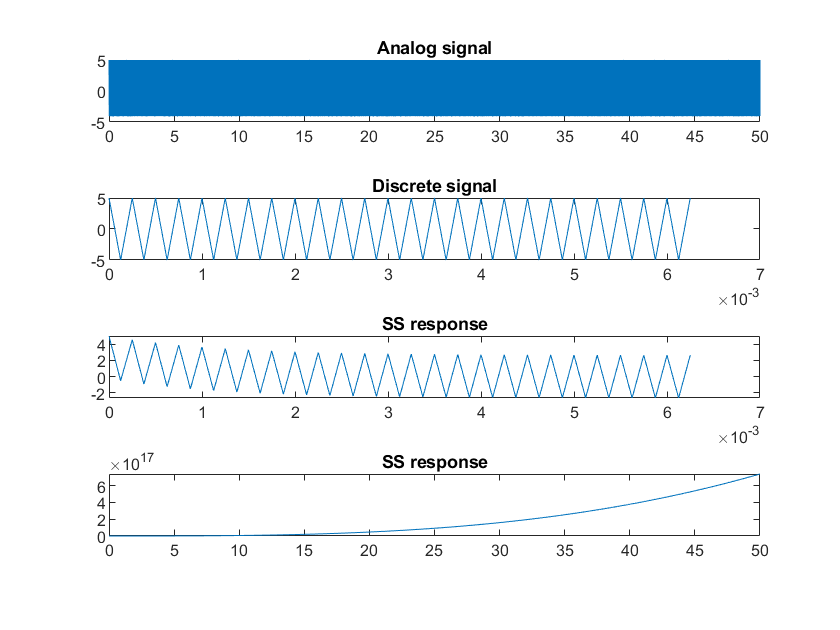

subplot(4,1,3)
plot(n*ts,y);
title('SS response')

ya=spline(n*ts,xd,t);
subplot(4,1,4)
plot(t,ya);
title('SS response')